# Primeira Prova - 25/09

João Guilherme Martins Jatobá

18.01790-8

ECM303 - Sistemas de Controle

**Boas Práticas**

clear all;        % Limpa as variáveis
clc;              % limpa a tela
close all;        % limpa os gráficos

**Questão 1**


$$\textrm{Gma}\left(s\right)=\frac{\textrm{Kp}\left(s+1\right)}{\left(s-4\right)\left(s+8\right)}$$


% Valores imutáveis
num1=[0 1 1];
denMa_1=[1 4 -32];
% Definindo ganho de malha aberta com Kp = 1
Kp_1=1;
Gma_1=tf(num1*Kp_1,denMa_1); % Ganho de malha aberta

denMf_1 = denMa_1+num1*Kp_1;
Gmf_1 = tf(num1*Kp_1,denMf_1); % Ganho de malha fechada


$$\textrm{Gmf}\left(s\right)=\frac{1}{1+\textrm{Gma}}=\frac{\textrm{Kp}\left(s+1\right)}{\left(s-4\right)\left(s+8\right)+\textrm{Kp}\left(s+1\right)}$$


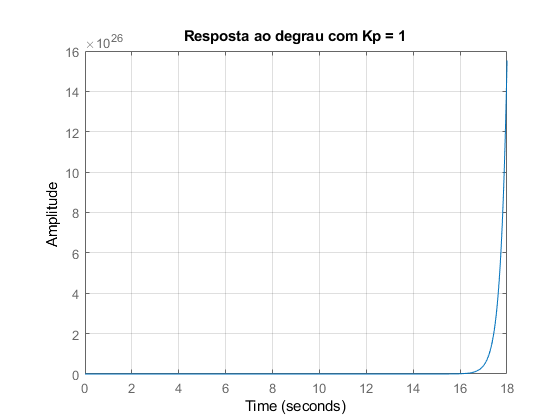

figure
step(Gmf_1) % Sistema eh instavel para Kp = 1
title("Resposta ao degrau com Kp = 1");
grid;

% Simulink mostra como esta comparação funciona


$$\mathrm{Gmf}\left(s\right)=\frac{Kp\left(s+1\right)}{s^2 +\left(4+Kp\right)s+\left(Kp-32\right)}$$


Aplicando Bhaskara no denominador para descobrir os pólos da função:


$$s=\frac{-\left(4+Kp\right)\pm \sqrt{{\left(4+Kp\right)}^2 -4*1*\left(Kp-32\right)}}{2*1}$$


Para estabilidade acontecer, Re{s}<0

*-Se *$\Delta
$*>0, Kp influencia Re{s}*

    Estudaremos $\sqrt{\Delta}$>0 já que influencia estabilidade

0>s


$$\begin{array}{l}
s=\frac{-b\pm \sqrt{\Delta }}{2}\to 0>-b\pm \sqrt{\Delta }\\
b>\pm \sqrt{\Delta }\to b^2 >\Delta \\
b^2 -4ac<b^2 \\
4*1*\left(Kp-32\right)>0\\
Kp>32\;\;\;\;\;\;\left(\mathrm{I}\right)
\end{array}$$


*-Se *$\Delta
$*<0, Kp não influencia Re{s}*

    Estudaremos somente $\frac{-b}{2}$

0>s


$$\begin{array}{l}
0>\frac{-b}{2}\\
0>-\left(4+\textrm{Kp}\right)\\
\textrm{Kp}>-4\;\;\;\;\;\left(\textrm{II}\right)
\end{array}$$


Utilizando os resultados I e II


$$\textrm{Kp}=\mathrm{I}\cup \textrm{II}=\;\right\rbrack 32,\infty \left\lbrack \;\textrm{ou}\;\textrm{Kp}>32$$


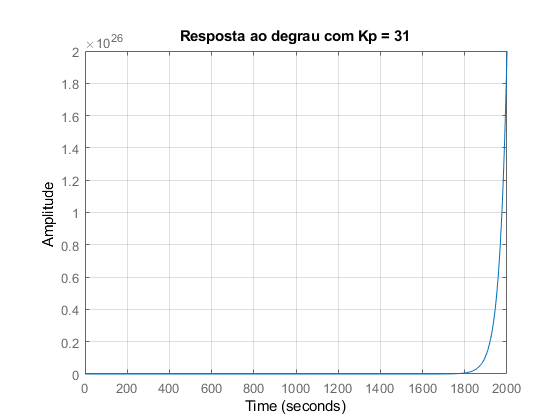

% Testando resultados
% Teste antes do limite
Kp_1=31; 
denMf_1 = denMa_1+num1*Kp_1;
Gmf_1 = tf(num1*Kp_1,denMf_1); % Ganho de malha fechada

figure
step(Gmf_1) 
title("Resposta ao degrau com Kp = 31");
grid;

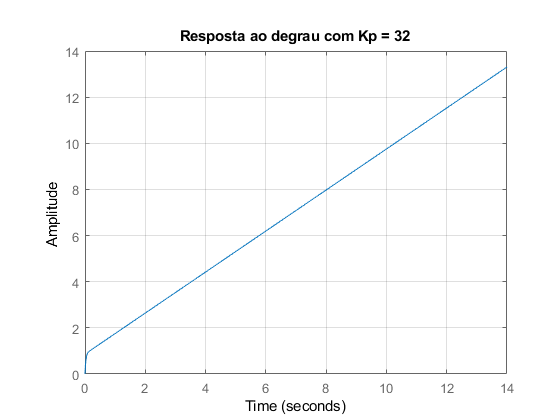


%Teste logo no limite
Kp_1 = 32; 
denMf_1 = denMa_1+num1*Kp_1;
Gmf_1 = tf(num1*Kp_1,denMf_1); % Ganho de malha fechada

figure
step(Gmf_1) 
title("Resposta ao degrau com Kp = 32");
grid;


%Teste dentro do domínio de Kp
Kp_1 = 33;
denMf_1 = denMa_1+num1*Kp_1;
Gmf_1 = tf(num1*Kp_1,denMf_1); % Ganho de malha fechada

figure
step(Gmf_1) 
title("Resposta ao degrau com Kp = 33 e 160");
grid;hold;

Current plot held


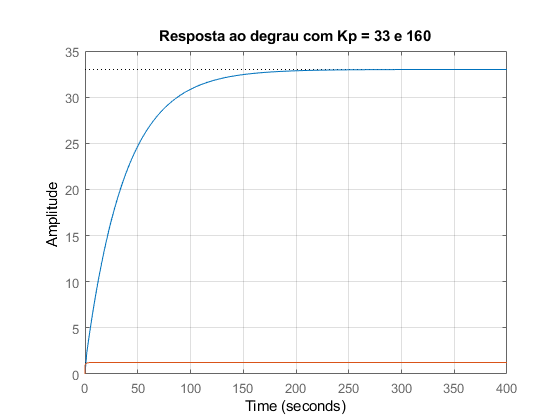

Kp_1 = 160;
denMf_1 = denMa_1+num1*Kp_1;
Gmf_1 = tf(num1*Kp_1,denMf_1);
step(Gmf_1) 

**Questão 2**

Regras que devem ser seguidas para achar Kp:

1-) O erro estacionario ao degrau deve ser nulo

2-) O erro estacionario quando a entrada R(s) for uma rampa deve ser inferior a 10%

3-) O amortecimento deve ser: ζ > 0.707

4-) O sobressinal deve ser: Mp< 20%


$$\textrm{Gma}=\frac{4}{s\left(s+4\right)}$$


% Aceitei que pelo controlador ser proporcional ao ganho, pode se dizer que
% Gma também é, já que Gma(s) = Gprojeto(s)*Gcontrolador(s)

Com Kp na função:


$$\textrm{Gma}=\frac{4\textrm{Kp}}{s\left(s+4\right)}$$


% Início da análise da questão
Kp_2=2; % Chute inicial para Kp
s = tf('s');
Gma_2=tf(4,[1 4 0]); % Ganho de malha aberta
Gmf_2 = tf(4*Kp_2,[1 4 4*Kp_2]) % Ganho de malha fechada

Gmf_2 =
 
        8
  -------------
  s^2 + 4 s + 8
 
Continuous-time transfer function.



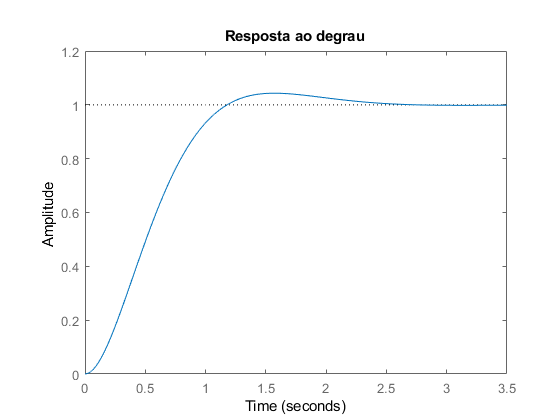


num_mf = cell2mat(Gmf_2.Numerator);
den_mf = cell2mat(Gmf_2.Denominator);

figure
step(Gmf_2)
title("Resposta ao degrau");


$$E\left(s\right)=\frac{1}{1+\textrm{Gma}}*R\left(s\right)$$


*Análise da regra 1:*

Transformada de Laplace de um degrau: $L\left\lbrace \epsilon \left(t\right)\right\rbrace =R\left(s\right)=\frac{1}{s}$


$$E\left(s\right)=\frac{s\left(s+4\right)}{s\left(s+4\right)+4\;\textrm{Kp}}*\frac{1}{s}$$



$$\lim_{t\to \infty } \;e\left(t\right)=\lim_{s\to 0} \;s*E\left(s\right)=\lim_{s\to 0} \;s*\frac{s\left(s+4\right)}{s\left(s+4\right)+4\;\textrm{Kp}}*\frac{1}{s}$$



$$\begin{array}{l}
=\lim_{s\to 0} \;\frac{s\left(s+4\right)}{s\left(s+4\right)+4\;\textrm{Kp}}=\;\frac{0\left(0+4\right)}{0\left(0+4\right)+4\;\textrm{Kp}}\\
=\frac{0}{4\;\textrm{Kp}\;}
\end{array}$$


% Erro ao degrau é nulo


$$\begin{array}{l}
\lim_{t\to \infty } \;e\left(t\right)=0\\
0=\frac{0}{4\;\textrm{Kp}}
\end{array}$$


% Kp não influencia na estabilidade do sistema, logo o erro sempre é zero
% para um degrau

*Análise da regra 2:*

Transformada de Laplace de uma rampa: $L\left\lbrace t*\epsilon \left(t\right)\right\rbrace =R\left(s\right)=\frac{1}{s^2 }$


$$E\left(s\right)=\frac{s\left(s+4\right)}{s\left(s+4\right)+4\;\textrm{Kp}}*\frac{1}{s^2 }$$



$$\lim_{t\to \infty } \;e\left(t\right)=\lim_{s\to 0} \;s*E\left(s\right)=\lim_{s\to 0} \;s*\frac{s\left(s+4\right)}{s\left(s+4\right)+4\;\textrm{Kp}}*\frac{1}{s^2 }$$



$$\begin{array}{l}
=\lim_{s\to 0} \;\frac{s+4}{s\left(s+4\right)+4\;\textrm{Kp}}=\;\frac{0+4}{0\left(0+4\right)+4\;\textrm{Kp}}\\
=\frac{4}{4\;\textrm{Kp}\;}=\frac{1}{\textrm{Kp}}
\end{array}$$


% Erro à rampa é menor que 10% - dado do enunciado


$$\begin{array}{l}
\underset{t\to \infty }{\mathrm{lim}} \;e\left(t\right)<0,1\\
0,1>\frac{1}{Kp}\to Kp>10
\end{array}$$


% Pela regra 2, Kp deve ser maior que 10

Para as regras 3 e 4, será usada a seguinte equação:

$\textrm{Mp}\left\lbrack %\right\rbrack =100*e^{\frac{-\pi \zeta }{\sqrt{1-\zeta^2 }}}$, onde quanto maior $\zeta
$, menor será o *Mp*

*Análise da regra 3 (*$\zeta >0,707$*):*


$$\begin{array}{l}
\textrm{Mp}\left\lbrack %\right\rbrack =100*e^{\frac{-\pi *0,707}{\sqrt{1-{0,707}^2 }}} \\
\textrm{Mp}\left\lbrack %\right\rbrack =100*e^{\frac{-2,221}{0,707}} \\
\textrm{Mp}\left\lbrack %\right\rbrack =4,326\;%
\end{array}$$


*Análise da regra 4 (Mp<20%):*


$$\begin{array}{l}
0,2=e^{\frac{-\pi \zeta }{\sqrt{1-\zeta^2 }}} \\
\ln \left(0,2\right)=\frac{-\pi \zeta }{\sqrt{1-\zeta^2 }}\\
{1,609}^2 \left(1-\zeta^2 \right)=\pi^2 \zeta^2 \\
\zeta =\sqrt{\frac{1,{609}^2 }{12,459}}=\sqrt{0,207}=0,4559
\end{array}$$


Vendo os resultados das análises de 3 e 4, conclui-se que a regra 3 garante a 4, mas não o contrário.

% Agora analisando Gmf com as conclusões anteriores

Sabendo que $\textrm{Gmf}=\frac{{w_n }^2 }{s^2 +2\zeta w_n s+{w_n }^2 }=\frac{\textrm{Gma}}{1+\textrm{Gma}}$,

    chegamos em $\textrm{Gmf}=\frac{4\textrm{Kp}}{s^2 +4s+4\textrm{Kp}}$

% Descobrindo Wn


$$\begin{array}{l}
2\zeta w_n =4\\
\zeta w_n =2\\
w_n =\frac{2}{0,707}=2,83
\end{array}$$


% Descobrindo o ganho do sistema


$$\begin{array}{l}
{w_n }^2 =4\textrm{Kp}\\
2,{83}^2 =4\textrm{Kp}\\
\textrm{Kp}=2
\end{array}$$


% Considerações

Não existe ganho Kp que satisfaça todas as condições.

Mesmo que peguemos o menor valor de $\zeta
$(0,707), o Kp ainda não será aceito pela regra 2. E ainda se pegarmos um valor maior de $\zeta
$, o valor de Kp diminuiria, já que a relação entre os dois é indireta - enquanto um aumenta, o outro diminui.

**Questão 3**

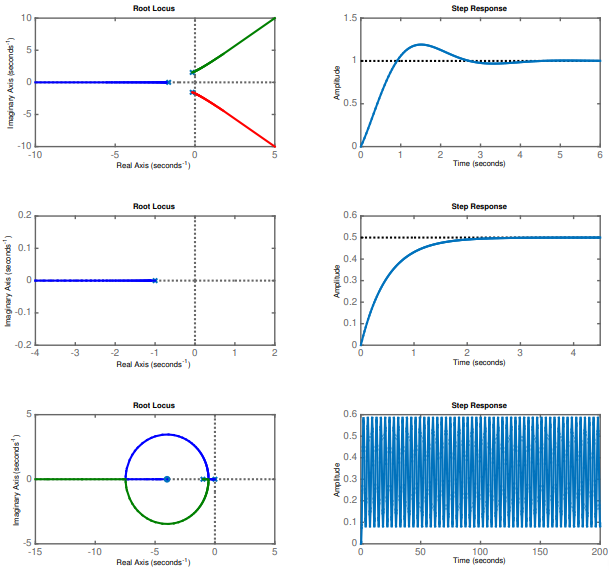

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

 Análise do primeiro lugar de raízes:

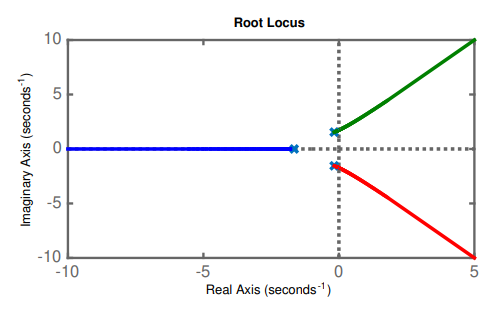

% Respostas assim têm como entrada em Laplace denominadores de terceira
% ordem, logo vamos criar uma função de transferência exemplar.
% Esta análise é feita pelo gráfico ter três lugares de raízes diferentes,
% logo o sistema é de terceira ordem.
% raizes: -0,1+1,4i   -0,1-1,4i    -1.5


$$\begin{array}{l}
\left(s+1,5\right)\left(s+0,1-1,4i\right)\left(s+0,1+1,4i\right)=s^3 +1,7s^2 +2,27s+2,955\\

\end{array}$$


Limite de estabilidade: $G\left(s\right)=-1\to G\left(j\;w_x \right)=-1$


$$\begin{array}{l}
Kp=-{\left(j\;w_x \right)}^3 -1,7{\left(j\;w_x \right)}^2 -2,27j\;w_x -2,955\\
Kp=j\;{w_x }^3 +1,7\;{w_x }^2 -2,27\;j\;w_x -2,955\\
0={w_x }^3 -2,27w_x \to w_x =\sqrt{2,27}=1,712\\
Kp=1,712*2,27-2,955
\end{array}$$



var2 = 2.27

var2 = 2.2700

var1 = sqrt(var2)

var1 = 1.5067

var3 = 2.955

var3 = 2.9550


Kp_3_1 = var1*var2-var3

Kp_3_1 = 0.4651

numM_3_1=[0 0 0 Kp_3_1];
denM_3_1 = [1 var1 var2 var3];
Gma_3_1= tf(numM_3_1,denM_3_1)

Gma_3_1 =
 
               0.4651
  --------------------------------
  s^3 + 1.507 s^2 + 2.27 s + 2.955
 
Continuous-time transfer function.



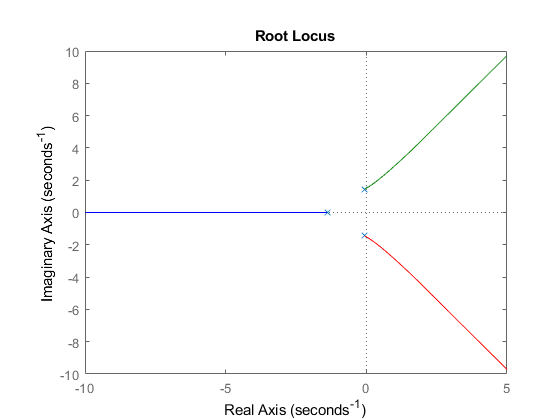

% Cálculo de Ganho de malha aberta
figure 
rlocus(Gma_3_1)
ylim([-10 10])
xlim([-10 5])


Gmf_3_1 = tf(numM_3_1,denM_3_1+numM_3_1)

Gmf_3_1 =
 
              0.4651
  -------------------------------
  s^3 + 1.507 s^2 + 2.27 s + 3.42
 
Continuous-time transfer function.



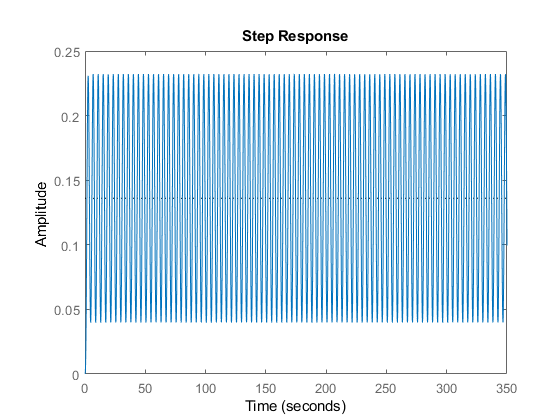

% Um gráfico
figure
step(Gmf_3_1)

A resposta ao degrau condiz com a seguinte (com erro de amplitude):

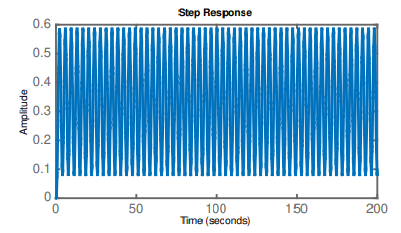


$$\mathrm{Gma}\left(s\right)=K\;\frac{0,4651}{s^3 +1,507\;s^2 +2,27s+3,42}$$



% Vendo a resposta, vemos que o resultado tem aparência parecida, mas
% temos erro na amplitude, de aproximadamente 2,5 vezes.


% Isso provavelmente ocorreu por causa de uma leitura errada do gráfico, já
% que não há delimitações extas de onde se encontram as raízes da função.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Análise do segundo lugar de raízes:

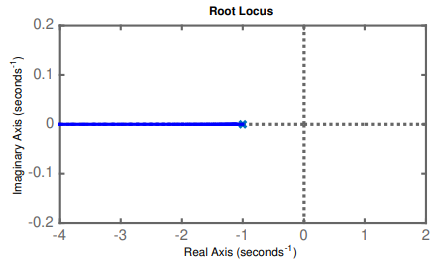

% Admitindo a primeira forma canonica de Gmf:
Kp_3_2 = 1;
Gma_3_2 = tf(Kp_3_2,[1 1])

Gma_3_2 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



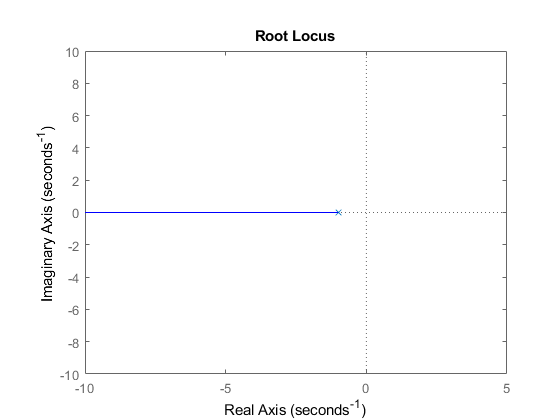

figure
rlocus(Gma_3_2)
ylim([-10 10])
xlim([-10 5])


% Pelo gráfico, percebe-se que o gráfico está parecido com o segundo da segunda
% coluna. Colocando no sisotool(Gmf_3_2), vemos que o lugar das raízes é
% igual ao do segundo gráfico da primeira coluna.
% Ainda nesse software, quando a raiz é igual a -2, o gráfico fica mais
% próximo do pedido, como mostrado a seguir:
Gmf_3_2 = tf(Kp_3_2,[1 1+Kp_3_2])

Gmf_3_2 =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.



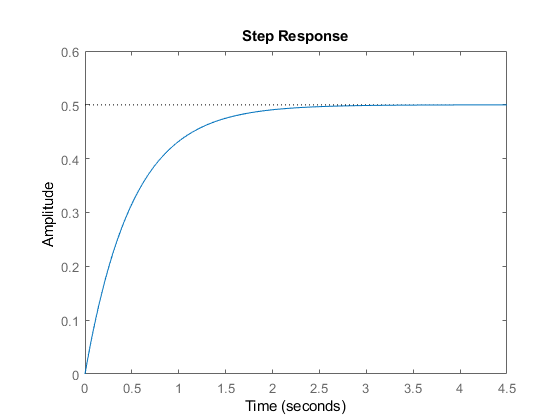


figure
step(Gmf_3_2)
ylim([0 0.6])
xlim([0 4.5])

A resposta ao degrau está mais próxima do gráfico do meio na coluna de degraus:

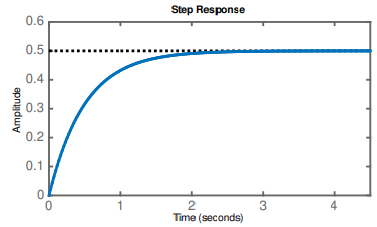


$$\mathrm{Gma}\left(s\right)=\frac{K}{s+1}$$


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Análise do terceiro lugar de raízes:

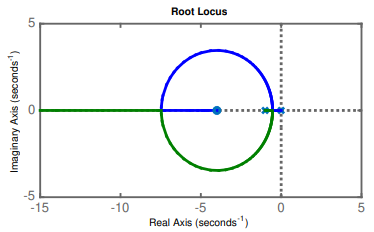

% Por ter circunferência, sabemos que há numerador dependente de s,
% enquanto embaixo se mantém dependendo de s^2
% Numerador = s+4, pois o centro da circunferência se aproxima de -4
numMA_3_3 = [0 1 4];
denMA_3_3 = [1 1 0];
Gma_3_3 = tf(numMA_3_3,denMA_3_3)

Gma_3_3 =
 
   s + 4
  -------
  s^2 + s
 
Continuous-time transfer function.



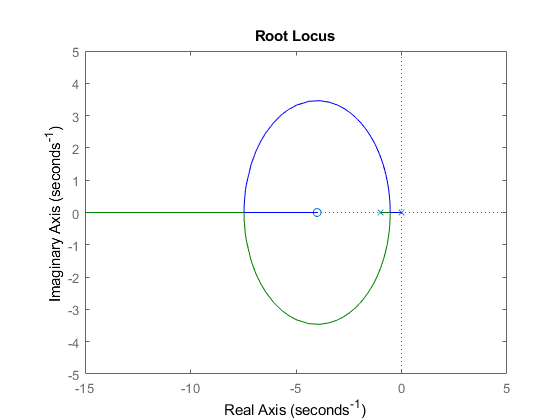


figure 
rlocus(Gma_3_3)
ylim([-5 5])
xlim([-15 5])


% Por meio do sisotool, vemos que sua resposta ao degrau é parecida com a
% em análise, logo podemos calcular o ganho em malha fechada

Gmf_3_3 = tf(numMA_3_3,denMA_3_3+numMA_3_3)

Gmf_3_3 =
 
      s + 4
  -------------
  s^2 + 2 s + 4
 
Continuous-time transfer function.



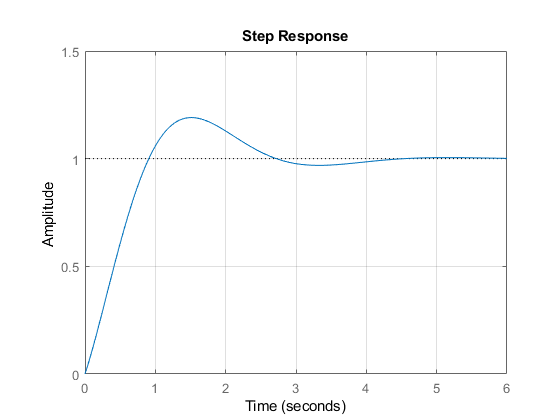

figure
step(Gmf_3_3)
ylim([0 1.5])
xlim([0 6])
grid;

O sinal resposta deu próximo do seguinte:

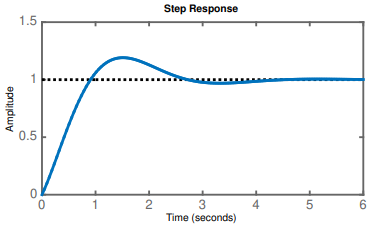

Portanto, determinou-se que $\mathrm{Gma}=\frac{K\left(s+4\right)}{s^2 +s}$

% Ainda nessa malha aberta, usando a função sisotool, vemos que há uma raiz na qual
% o gráfico aparenta ser o do meio na coluna dos degraus, com erro de
% amplitude em 2 vezes maior, como mostrado a seguir.

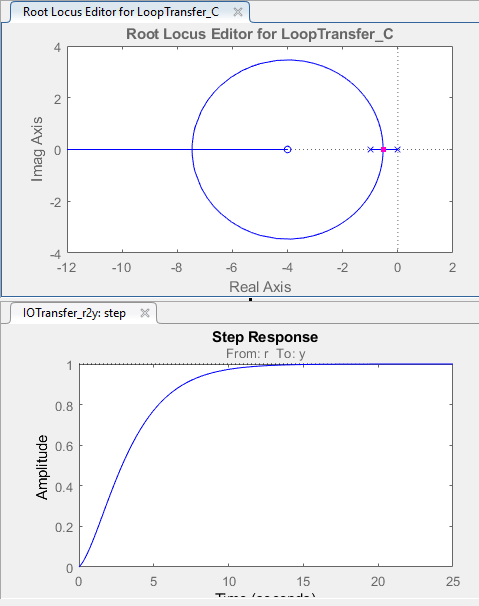

**Questão 4**

No gráfico da figura 2 temos a resposta ao degrau unitário de um sistema de segunda ordem operando em malha fechada, com realimentação unitária. Determine com base na análise temporal a função de transferência de malha fechada. É possível estimar a função de transferência de malha aberta? se sim qual seria?

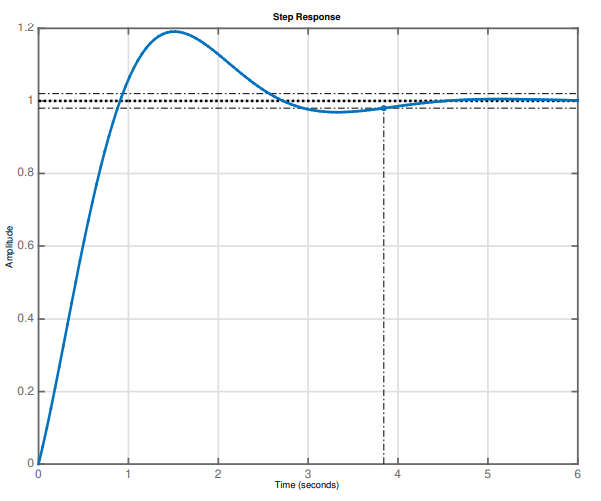

Afirmações:

Se $\textrm{Gmf}=\frac{\textrm{Gma}}{1+\textrm{Gma}}$, então $\mathrm{Gma}=\frac{\mathrm{Gmf}}{1-\mathrm{Gmf}}$

No gráfico, $\mathrm{Mp}\left(%\right)\approx 18$, $\textrm{Ts}\left(2%\right)\approx 3,8\;s$ 

Mp_4 = 0.18;
Ts_4 = 3.8;
zeta_4 = sqrt((log(Mp_4)^2)/(pi^2+(log(Mp_4)^2)));
wn_4 = 4/(Ts_4*zeta_4);

Usando a segunda forma canônica:


$$\textrm{Gmf}=\frac{{w_n }^2 }{s^2 +2\zeta w_n s+{w_n }^2 }$$


- chegamos em:

Gmf_4 = tf(wn_4^2,[1 2*zeta_4*wn_4 wn_4^2])

Gmf_4 =
 
          4.827
  ---------------------
  s^2 + 2.105 s + 4.827
 
Continuous-time transfer function.




figure
info = stepinfo(Gmf_4);
step(Gmf_4)
hold;

Current plot held


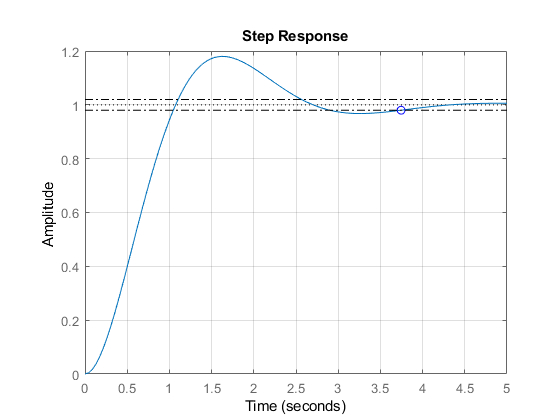

plot(info.SettlingTime,0.98,'bo')
plot(xlim,0.98*[1 1],'k-.')
plot(xlim,1.02*[1 1],'k-.')
grid;

O gráfico ficou próximo do dado, logo conclui-se que há como calcular Gmf, e com isso, Gma:


$$\begin{array}{l}
\mathrm{Gma}=\frac{\mathrm{Gmf}}{1-\mathrm{Gmf}}\\
\mathrm{Gma}=\frac{\frac{4,827}{s^2 +2s+4,827}}{1-\frac{4,827}{s^2 +2s+4,827}}\\
\mathrm{Gma}=\frac{4,827}{s^2 +2s}
\end{array}$$
